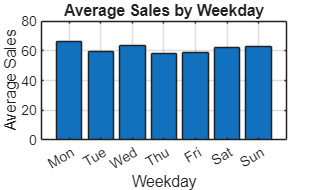

%% Step 2: Average Sales by Weekday (Bar Chart)

% 1) Load data
T = readtable("Demo_dataset.csv");

% 2) Ensure Date is datetime and create ordered Weekday
T.Date = datetime(T.Date,'InputFormat','yyyy-MM-dd');
T.Weekday = categorical( ...
    T.Weekday, {'Mon','Tue','Wed','Thu','Fri','Sat','Sun'}, ...
    'Ordinal', true);

% 3) Group by Weekday and compute mean Sales
[G, days] = findgroups(T.Weekday);
avgSalesByDay = splitapply(@mean, T.Sales, G);

% 4) Plot bar chart
bar(days, avgSalesByDay)
xlabel('Weekday')
ylabel('Average Sales')
title('Average Sales by Weekday')
grid on

% 5) Save the figure
saveas(gcf, 'avg_sales_by_weekday.png')